**35The cart and pole system**

Consider the cart-and-pole system here depicted:

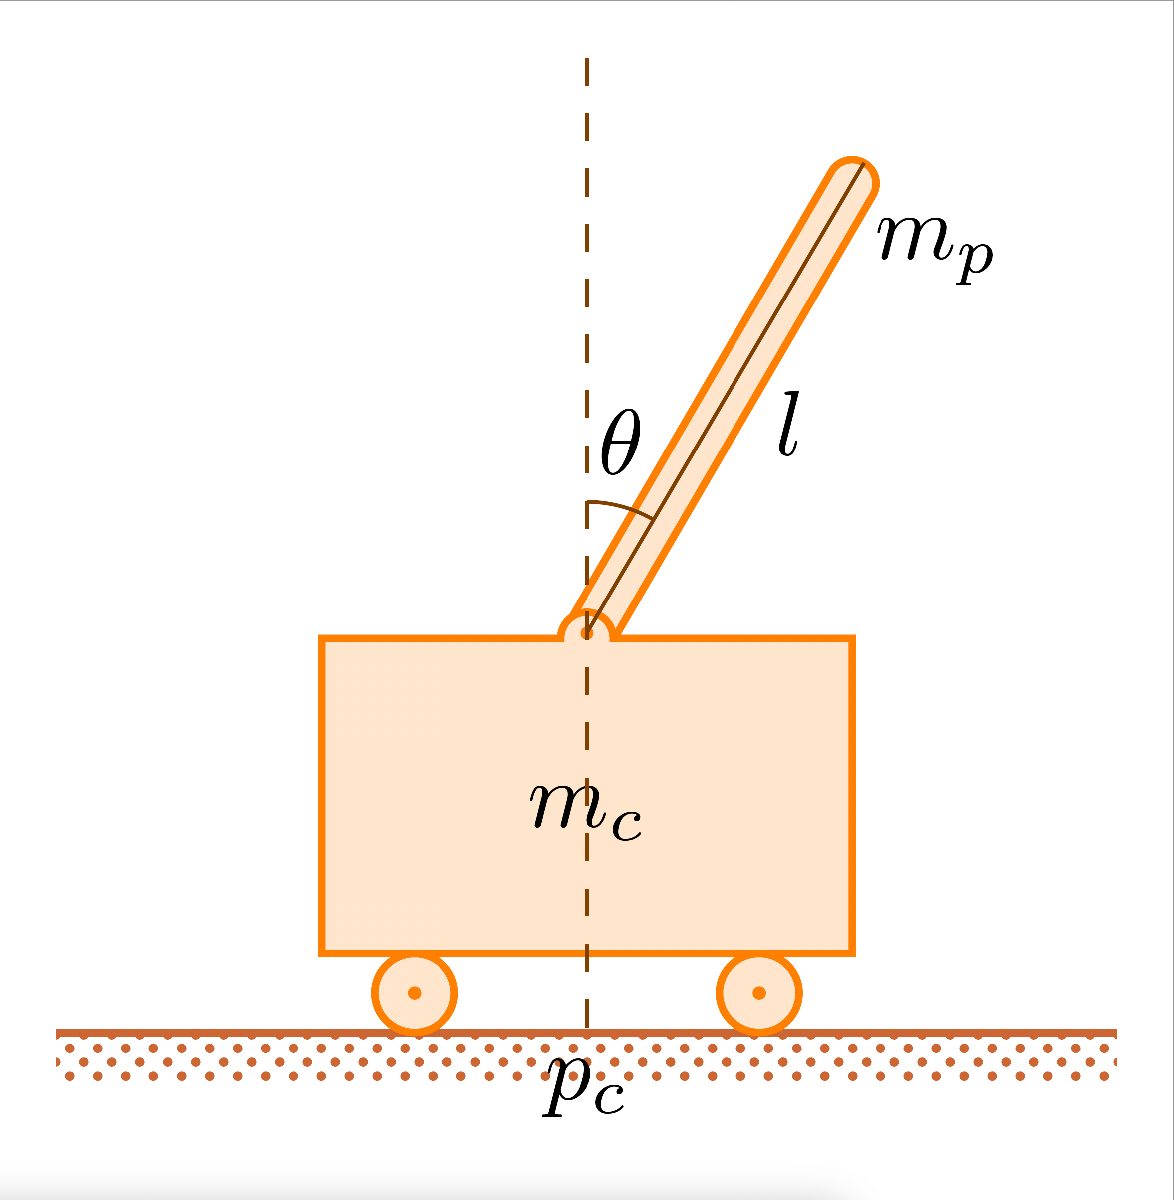

whose dynamics follows the following equations:


$$  \ddot{p}_c=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]}{m_c\,+\,m_p}$$



$$\ddot{\theta}=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)\,+\,\mu_c\,\text{sgn}\left(\dot{p}_c\right)}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$
   


$$(*)$$


where $g = 9.8\,\text{m/sec}$ is the gravitational acceleration, $m_c = 1\,\text{kg}$ is the cart mass, $m_p = 0.1\,\text{kg}$ is the pole mass, $l = 0.5\,\text{m}$ is the half-pole length, $\mu_p = 0.000002$ is the pole on cart friction coefficient, and $F:|F|\leq 10\,\text{N}$ is the force applied to cart's center of mass.

1. Clearly define an optimal control problem for pole balancing.

% Arguing the answer

**Slides topic_3, 6:8-12-25++**

**Slides topic_4, 3-26:27**

Sistema, funzione di tranzizione, task, performance index, stato iniziale, stato finale, orizzonte infinito

Diciamo che voglio che segua una traiettoria dove theta rimane 0, quindi in realtà ha k=inf

N.B. pi* is an argmin because I'm defining a Tracking optimal control with the desired trajectory equal to 0, like is written in the previous line

2. Is the LQR applicable in its simple form on the system? If not what is missed?

% Arguing the answer both in case of positive and negative answer

**NO: Slides topic_4, 34:35 and so on till I explain the solution**

3. Design an LQR for the linearized version of the cart and pole obtained in the previous hands-on. Justify all the design choices and perform all the required checks

% Provide the code

clear all
close all
clc

load cart_pole_matrix_lin.mat;

cp_cont = ss(A, B, C, D);  %computing the continuous system
cp_dis = c2d(cp_cont, 0.01);  %computiung the discrete system from the previous one

obs_matrix = obsv(cp_dis.A, cp_dis.C);  %computing the observable matrix
is_obs = length(A) - rank(obs_matrix)  %check if the system is fully observable

is_obs = 0

reach_matrix = ctrb(cp_dis.A, cp_dis.B);  %computing the reachable matrix
is_reach = length(A) - rank(reach_matrix) %check if the system is fully reachable

is_reach = 0

R = 10;    
Q = [1  0  0  0;
     0  0  0  0;
     0  0  10  0;
     0  0  0  0];

K= dlqr(cp_dis.A, cp_dis.B, Q, R)  %the command provide the vector K for an infinite horizon control

K =    -0.3028   -0.9543  -25.5205   -6.4607


4. Simulate the linearized cart and pole system controlled by an LQR. Plot the significant behaviors

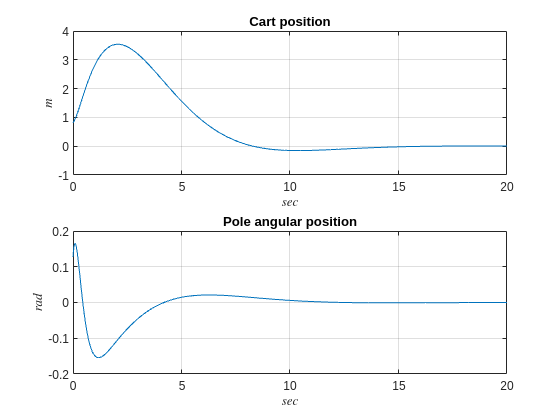

% Provide the code, an animation of the system the plots of the state evolution

Acl = cp_dis.A - cp_dis.B * K;
Bcl = cp_dis.B;
Ccl = cp_dis.C;
Dcl = 0;

x_0 = rand(1,4);   %generate random initial condition
x_0_non_lin = x_0;

Ts = 0;
for i=1:1:2001
    Ts = [Ts Ts(end)+0.01];
end

cp_cl = ss(Acl, Bcl, Ccl, Dcl, 0.01);   %computing the discrete system with the lqr control

j1 = 1;
u = [0 -K*x_0'];

for i=1:1:2001

    [x, t] = lsim(cp_cl, [0 -K*x_0'], Ts(i):0.01:Ts(i+1), x_0);
    
    sz = size(x);
    
    j2 = j1 + sz(1)-1;

    xout([j1:j2], :) = x;
    tout([j1:j2], :) = t;

    j1 = j2;

    x_0 = x(end, :);
    u(1) = u(2);
    u(2) = -K*((x_0'));
    
end

subplot(2,1,1);
plot(tout, xout(:,1));
xlabel("$sec$", Interpreter="latex");
ylabel("$m$", Rotation=90, Interpreter="latex");
grid on
xlim([0 20]);
title("Cart position");

subplot(2,1,2);
plot(tout, xout(:,3));
grid on
title("Pole angular position");
xlabel("$sec$", Interpreter="latex");
ylabel("$rad$", Rotation=90, Interpreter="latex");
xlim([0 20]);

5. Simulate the non-linear cart and pole system controlled by the previously obtained LQR. Plot the significant behaviors

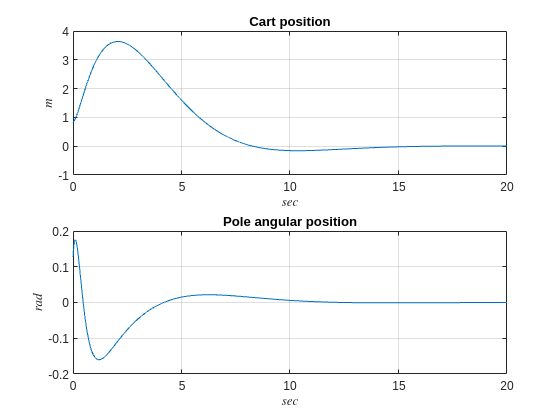

% Provide the code, an animation of the system the plots of the state evolution

g = 9.8;
mc = 1;
mp = 0.1;
l = 0.5;
mu_p = 2e-6;

x_0 = x_0_non_lin;

Ts = 0;
for i=1:1:2001
    Ts = [Ts Ts(end)+0.01];
end

j1 = 1;
U = 0;

for i=1:1:2001

    [t, x] = ode45(@(t,x)cart_pend_for(t, x, g, mp, mc, l, mu_p, U), [Ts(i) Ts(i+1)], x_0);
   
    sz = size(x);
    
    j2 = j1 + sz(1)-1;

    xout_non_lin(j1:j2, :) = x;
    tout_non_lin(j1:j2, :) = t;

    j1 = j2;

    x_0 = x(end, :);
    U = -K*((x_0'));
end

subplot(2,1,1);
plot(tout_non_lin, xout_non_lin(:,1));
xlabel("$sec$", Interpreter="latex");
ylabel("$m$", Rotation=90, Interpreter="latex");
grid on
xlim([0 20]);
title("Cart position");

subplot(2,1,2);
plot(tout_non_lin, xout_non_lin(:,3));
grid on
title("Pole angular position");
xlabel("$sec$", Interpreter="latex");
ylabel("$rad$", Rotation=90, Interpreter="latex");
xlim([0 20]);

6. Comment results obtained in the two simulations

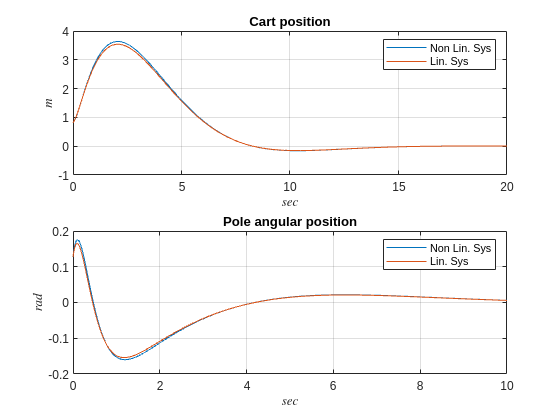

% Arguing the answer

subplot(2,1,1);
plot(tout_non_lin, xout_non_lin(:,1));
hold on;
plot(tout, xout(:,1));
hold off;
xlabel("$sec$", Interpreter="latex");
ylabel("$m$", Rotation=90, Interpreter="latex");
grid on
xlim([0 20]);
title("Cart position");
legend("Non Lin. Sys", "Lin. Sys");

subplot(2,1,2);
plot(tout_non_lin, xout_non_lin(:,3));
hold on;
plot(tout, xout(:,3));
hold off;
grid on
title("Pole angular position");
xlabel("$sec$", Interpreter="latex");
ylabel("$rad$", Rotation=90, Interpreter="latex");
xlim([0 10]);
legend("Non Lin. Sys", "Lin. Sys");